%2nd Order Homogeneous ODEs
%Question 1)
clear

syms x(t)

%coefficients
a = 1;
b = 2;
c = 2;

%declaring ODE
ode = a*diff(x,t,2) + b*diff(x,t) + c*x == 0

$$ode(t) = \frac{\partial^{2}}{\partial t^{2}}x\left(t\right)+2\,\frac{\partial }{\partial t}x\left(t\right)+2\,x\left(t\right)=0$$


%solving ode
dsolve(ode) %finding general solution

$$ans = C_{1}\,{\mathrm{e}}^{-t}\,\cos\left(t\right)-C_{2}\,{\mathrm{e}}^{-t}\,\sin\left(t\right)$$


%question c)
syms m %declaring symbolic variable
eqn = m^2 + 2*m + 2 == 0 %declaring quadratic

$$eqn = m^{2}+2\,m+2=0$$

solve(eqn,m) %solving quadratic

$$ans = \left(\begin{array}{c} -1-\mathrm{i}\\ -1+\mathrm{i} \end{array}\right)$$

%Question 2)
clear

syms x(t) m

%coefficients
a = 1;
b = 4;
c = 5;

%finding roots
eqn = a*m^2 + b*m + c == 0 %declaring quadratic

$$eqn = m^{2}+4\,m+5=0$$

solve(eqn,m)

$$ans = \left(\begin{array}{c} -2-\mathrm{i}\\ -2+\mathrm{i} \end{array}\right)$$


dx(t) = diff(x,t) %declaring first order diff

$$dx(t) = \frac{\partial }{\partial t}x\left(t\right)$$


%declaring initial conditions
IC = [x(0)==1 dx(0)==-3]

$$IC = \left(\begin{array}{cc} x\left(0\right)=1 & \left({\left(\frac{\partial }{\partial t}x\left(t\right)\right)|}_{t=0}\right)=-3 \end{array}\right)$$


%declaring ODE
ode = a*diff(x,t,2) + b*diff(x,t) + c*x == 0

$$ode(t) = \frac{\partial^{2}}{\partial t^{2}}x\left(t\right)+4\,\frac{\partial }{\partial t}x\left(t\right)+5\,x\left(t\right)=0$$


%solving ode
dsolve(ode) %finding general solution

$$ans = C_{1}\,{\mathrm{e}}^{-2\,t}\,\cos\left(t\right)-C_{2}\,{\mathrm{e}}^{-2\,t}\,\sin\left(t\right)$$

sol = dsolve(ode,IC) %finding particular solution

$$sol = {\mathrm{e}}^{-2\,t}\,\left(\cos\left(t\right)-\sin\left(t\right)\right)$$

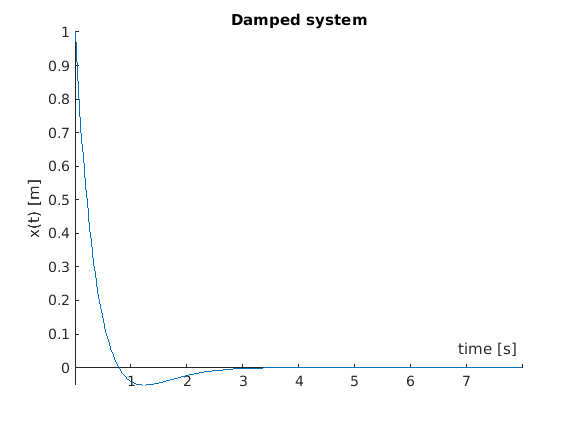


%plotting particular solution
fplot(sol, [0 8])

%beautifying curve
ax = gca;
ax.XAxisLocation = "origin";
ax.YAxisLocation = "origin";
box off

%labelling graph
xlabel("time [s]")
ylabel("x(t) [m]")
title("Damped system")


%Question 3
%declaring initial conditions
IC2 = [x(0)==1 dx(0)==0];

%checking solution with new constraints
sol2 = dsolve(ode,IC2)

$$sol2 = {\mathrm{e}}^{-2\,t}\,\left(\cos\left(t\right)+2\,\sin\left(t\right)\right)$$

%Question 4
clear
syms x(t) dx(t) %declaring symbolic variables

%declaring ODE
ode = diff(x,t,2) +5*x == 0

$$ode(t) = \frac{\partial^{2}}{\partial t^{2}}x\left(t\right)+5\,x\left(t\right)=0$$


%stating intiail conditions
dx(t) = diff(x,t) %generating variable for derivative

$$dx(t) = \frac{\partial }{\partial t}x\left(t\right)$$

IC = [x(0)==1 dx(0)==0]

$$IC = \left(\begin{array}{cc} x\left(0\right)=1 & \left({\left(\frac{\partial }{\partial t}x\left(t\right)\right)|}_{t=0}\right)=0 \end{array}\right)$$


%solving ode
sol = dsolve(ode,IC)

$$sol = \cos\left(\sqrt{5}\,t\right)$$

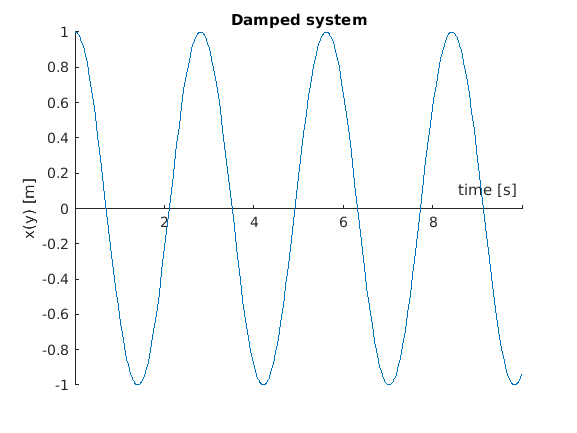


%plotting
fplot(sol, [0 10])

%beautifying curve
ax = gca;
ax.XAxisLocation = "origin";
ax.YAxisLocation = "origin";
box off

%labelling graph
xlabel("time [s]")
ylabel("x(y) [m]")
title("Damped system")